# Composition analysis using TGA

Run M1 to get TGA data into DTG, then can run this one

Aug, 2023 Nanta

## 1. Load TGA data

clear variables

%%% TGA data 
DTGdata_all = load('DTGdata_biomass.mat');

Data = "PineExtFree_20Kpm_R1";
Name = "Pine Ext-free";

## 2. Input Extractives and Ash(partial) data

%%% Input manually
%%% Extractives (wt%db) and ash (wt% extractive-free basis)
Ext = 4.6

Ext = 4.6000

AshE = 0.11

AshE = 0.1100

% convert ash content to dry basis
Ash_db = AshE*(1-Ext)

Ash_db = -0.3960

## 3. Fit DTG curves 

beta = 20

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         2      0.02523        81       834     1.782e-06

MultiStart completed the runs from all start points.

The local solver ran once and converged with a positive local solver exit flag.


bb_fm =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063


fval_msfm = 0.0252

exitflag = 1

outputMS = struct with fields:
                funcCount: 844
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.4266 246.0759 0.5366 11.6999 145.0650 0.2331 18.2503 31.5419 0.2063]
        Fval: 0.0252
    Exitflag: 2
      Output: [1×1 struct]
          X0: {[11.9000 218 0.5000 11.1000 105.2000 0.3000 17.8000 53.5000 0.2000]}


fval_msfm = 0.0252

Rsq_msfm = 0.9986

T_peakC1 = 380.5602

T_peakC2 = 336.5946

T_peakC3 = 388.5516

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.fig"

figN = "./PineExtFree_20Kpm_R1_fit_3curves_23728.png"

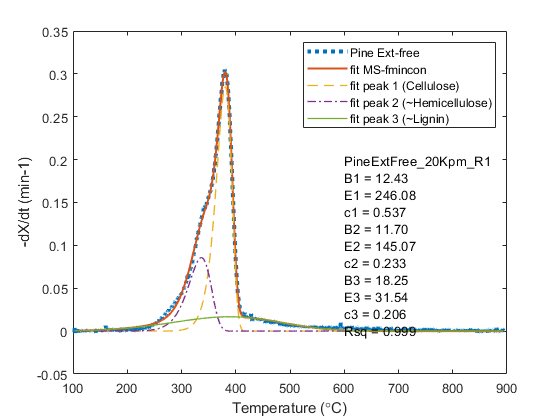

output =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063    0.9986  380.5602  336.5946  388.5516    0.9800


output =    12.4266  246.0759    0.5366   11.6999  145.0650    0.2331   18.2503   31.5419    0.2063    0.9986  380.5602  336.5946  388.5516    0.9800


outputMS = struct with fields:
                funcCount: 844
         localSolverTotal: 1
       localSolverSuccess: 1
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵The local solver ran once and converged with a positive local solver exit flag.'


solutions =   GlobalOptimSolution with properties:

           X: [12.4266 246.0759 0.5366 11.6999 145.0650 0.2331 18.2503 31.5419 0.2063]
        Fval: 0.0252
    Exitflag: 2
      Output: [1×1 struct]
          X0: {[11.9000 218 0.5000 11.1000 105.2000 0.3000 17.8000 53.5000 0.2000]}


% fit with 3 curves

[output, outputMS, solutions] = DTG_fit_3curves_biomass_fnc(DTGdata_all.(Data),Name,Data)

## 4. Calculate compositions

% Initial c from fitting
c_Cell = output(3)*100;
c_Hemi = output(6)*100;
c_Lig = output(9)*100;

% Reference char fraction of cellulose, hemicellulose and lignin
% Please see paper for references
Cell_char_ref = 7.26;
Hemi_char_ref = 20.0;
Lig_char_ref = 45.87;

% Adjust with char fraction
c_Cell_charadj = c_Cell/(100-Cell_char_ref);
c_Hemi_charadj = c_Hemi/(100-Hemi_char_ref);
c_Lig_charadj = c_Lig/(100-Lig_char_ref);

sum_c =  c_Cell_charadj + c_Hemi_charadj + c_Lig_charadj;

% normalize, and adjust with extractives and ash content
Cell_percentdb = c_Cell_charadj*(100-Ext-Ash_db)/sum_c

Cell_percentdb = 44.3035

Hemi_percentdb = c_Hemi_charadj*(100-Ext-Ash_db)/sum_c

Hemi_percentdb = 22.3069

Lig_percentdb = c_Lig_charadj*(100-Ext-Ash_db)/sum_c

Lig_percentdb = 29.1856


% check sum
Check = Ext + Ash_db + Cell_percentdb + Hemi_percentdb + Lig_percentdb;